# Use Linear Discriminant Analysis for Classification

`This script uses LDA to classify our EMG data.`

clear; close all; clc;

## Import Data

training = 'P1&P2';
testing = 'P1&P2';

Call a function to return the feature matrix. Each column of X is a measurement type, and each row is an observation. Xlabels is a cell that contains a label for each row of X.

[X, Xlabels] = getDataMatrix_ASB(training,testing);

## Primary For-Loop 

Before running the major loop in this script, we need to know how many samples we have.

numSamp = size(X,1);

Determine how many samples consitutes 80% of the data. 

trainSize = floor(numSamp*0.8);

For 10 iterations, this loop will randomly divide the data into two sets: a training set (80% of data) and a testing set (20% of data). It will reduce the training data using SVD, and then train a classifier in the SVD basis. The testing data will then be cast into the SVD basis, and the classifier will be evaluated on it.

for j = 1:10

Create a randomly assorted vector that contains all of the indices from 1 to the number of samples.  

    indexVector = randperm(numSamp)';

Use the first 80% of the index vector to pull training data from the primary data matrix. Also pull the corresponding labels.

    Xtraining = X(indexVector(1:trainSize),:);
    XtrainingLabels = Xlabels(indexVector(1:trainSize));

Use the remaing 20% of the data and labels as testing data.

    Xtesting = X(indexVector(trainSize+1:end),:);
    XtestingLabels = Xlabels(indexVector(trainSize+1:end));

Compute the singular value decomposition of the training data. Transpose the training data so that rows are measurements and columns are observations. This means the rows of v are now our observations.

    [u,s,v] = svd(Xtraining','econ');    

From the energy contained in each mode of u, it is clear that we don't need any modes past 40. Truncate our feature vector to the first 40 values. (see plot at end of script).

    trunVal = 40;
    vtrun = v(:,1:trunVal);

This truncated v data set will be our training set. As stated, columns are features and rows are observations.

    finalTrainingData = vtrun;    

Create our LDA classifier with fitcdiscr, uses a one vs all classification scheme.

    LDAclassifier = fitcdiscr(finalTrainingData,XtrainingLabels);

Before we can test this classifier on our testing data, we must cast the test data points into the SVD basis we created with our training data and truncate it. We need to transpose the testing data before our change of basis, because we transposed our training data before the SVD. Final transpose is required to put data into the format our classifier was trained in.

    testingDataInSVDBasis = s\u'*Xtesting';
    truncatedTestingData = testingDataInSVDBasis(1:trunVal,:);
    finalTestingData = truncatedTestingData';

Use the 'predict' function to label the testing data. Time how long this takes using 'tic' and 'toc' for diagnostic purposes.

    tic
    ourPredictions = predict(LDAclassifier, finalTestingData);
    timeVec(j) = toc;

Use the string compare function to see how many of the labels were correct. rightOrWrong will be an vector of 1's and 0's, where 1 means the prediction was correct.

    rightOrWrong = strcmp(ourPredictions,XtestingLabels);  

Add up the number of correct predictions and divide by number of total predictions to find accuracy. Save the accuracy during each iteration of the for-loop.

    accuracy(j) = (sum(rightOrWrong)/length(rightOrWrong))*100;
end

Compute the mean accuracy, standard deviation, and classification time for all 10 classifiers.

meanVal = mean(accuracy)

meanVal = 85.0868

stdVal = std(accuracy)

stdVal = 0.3506

meanTime = mean(timeVec)/length(ourPredictions)

meanTime = 1.0161e-05

Make a plot of the energy contained in each of the modes of u. 

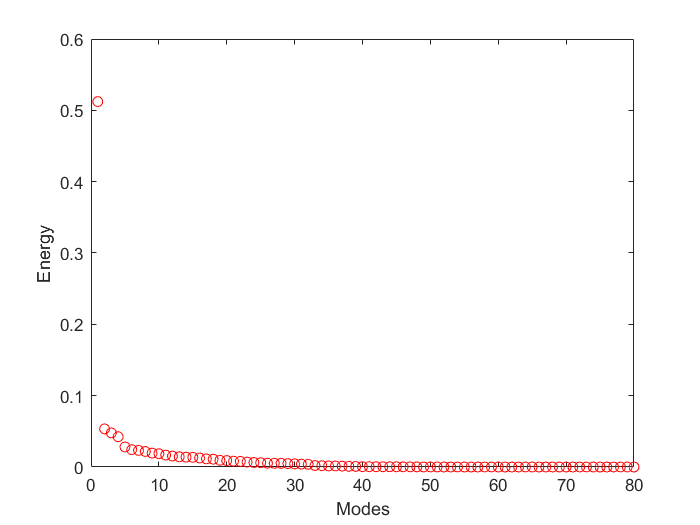

figure;
plot(diag(s)/sum(diag(s)),'ro');
xlabel('Modes')
ylabel('Energy')